## Pain dummy

#### Pain :: load dataset

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-03_CEScsA_24dofcsd/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0018.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.


sampleto = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-03_CEScsA_24dofcsd/1stLevel/sub-0008/con_0018.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 22363488 bytes
Loading image number:    56
Elapsed time is 5.018552 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 5421475  Bit rate: 22.37 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C',...
    'cueXcue_P', 'cueXcue_V', 'cueXcue_C',...
    'stim_P', 'stim_V', 'stim_C',...
    'stimXcue_P', 'stimXcue_V', 'stimXcue_C',...
    'stimXint_P', 'stimXint_V', 'stimXint_C',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C','simple_cue_G',...
    'simple_cueXcue_P', 'simple_cueXcue_V', 'simple_cueXcue_C','simple_cueXcue_G', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C','simple_stim_G',...
    'simple_stimXcue_P', 'simple_stimXcue_V', 'simple_stimXcue_C','simple_stimXcue_G',...
    'simple_stimXint_P', 'simple_stimXint_V','simple_stimXint_C', 'simple_stimXint_G'};

#### Pain :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

SPM12: spm_check_registration (v7759)              17:45:28 - 12/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


#### Pain :: Plot diagnostics, before l2norm

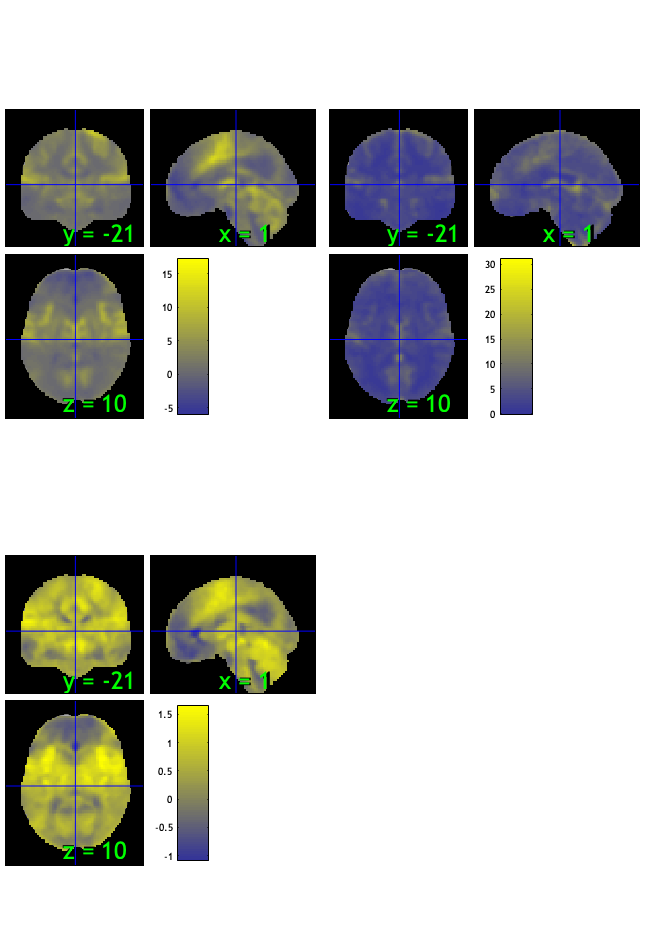

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 4 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 23.21%
Expected 2.80 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 3 images		Cases 10 20 31 
Uncorrected: 6 images		Cases 10 20 23 30 31 39 

Retained 7 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 42.86%
Expected 2.80 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 5 images		Cases 11 16 45 46 54 

Mahalanobis (cov and corr, q<0.05 corrected):
  3 images 
                               Outlier_count    Percentage
                       

SPM12: spm_check_registration (v7759)              17:45:49 - 12/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

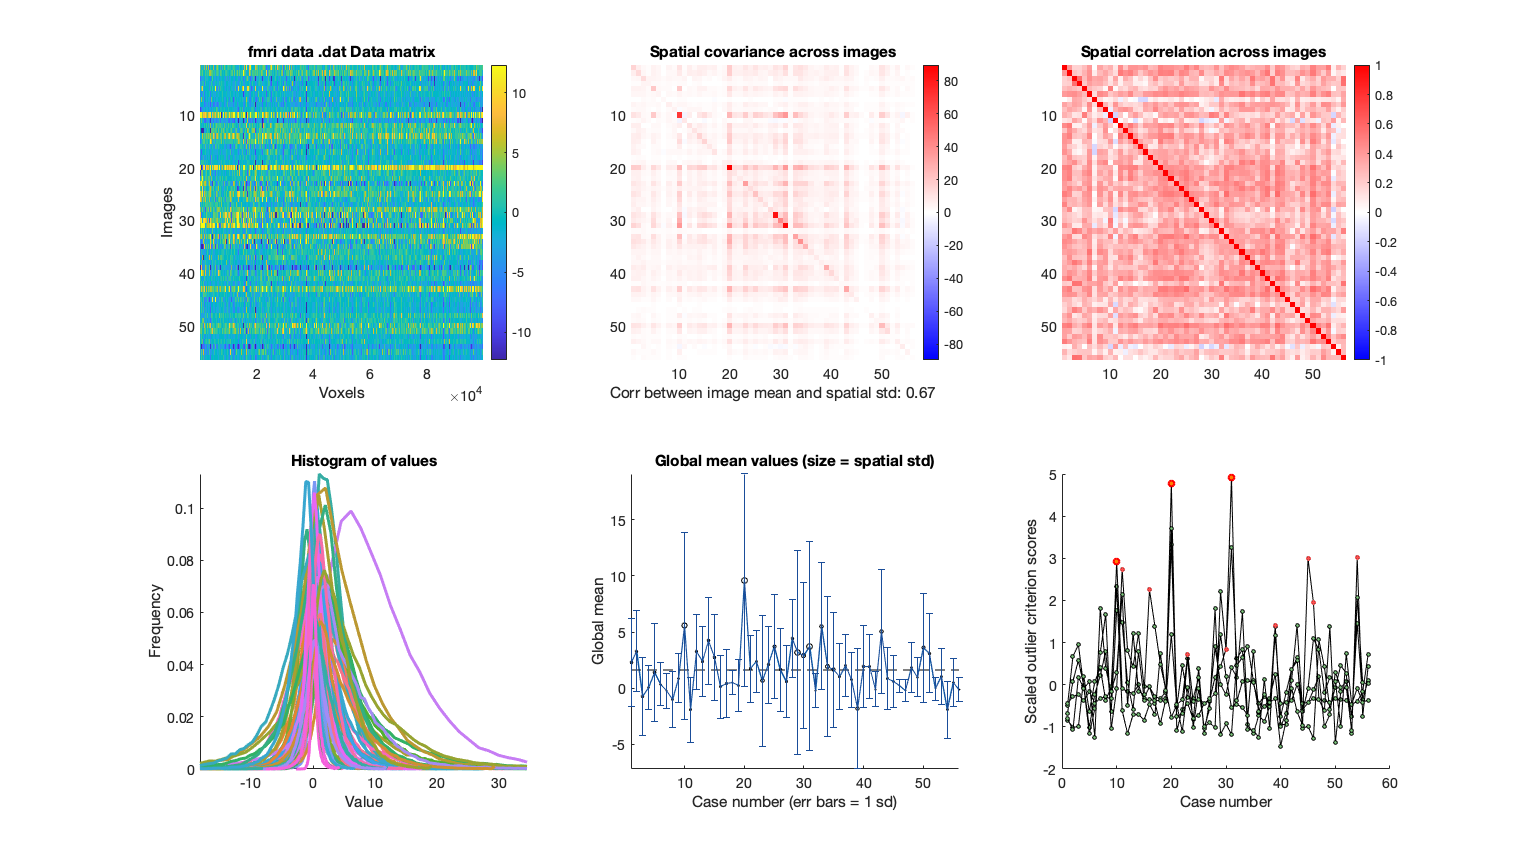

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


wh_outlier_uncorr = 56×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1


wh_outlier_corr = 56×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### Pain :: run robfit

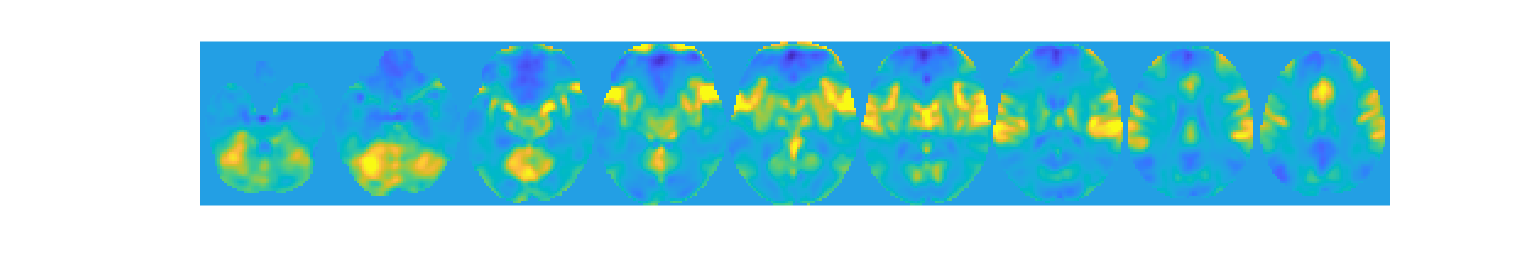

set(gcf,'Visible','on')

figure ('Visible', 'on');
drawnow, snapnow;

#### Pain :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))

current length is 56


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×53 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [53×12 char]
              fullpath: [56×118 char]
           files_exist: [56×1 logical]
               history:

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×53 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [53×12 char]
              fullpath: [53×118 char]
           files_exist: [56×1 logical]
               history:

con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×53 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [53×12 char]
              fullpath: [53×118 char]
           files_exist: [53×1 logical]
               history:

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 3 participants, size is now 53


#### Pain :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Pain :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


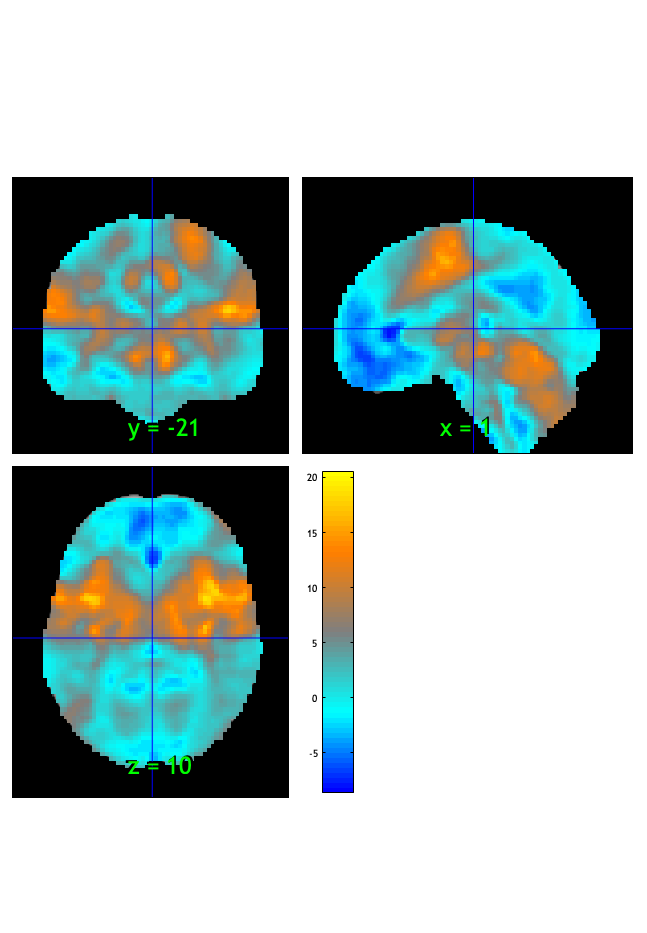

SPM12: spm_check_registration (v7759)              17:45:55 - 12/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×1 struct}


orthviews(t)

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.029521

Image   1
 36 contig. clusters, sizes   1 to 56727
Positive effect: 50412 voxels, min p-value: 0.00000000
Negative effect: 8534 voxels, min p-value: 0.00000000


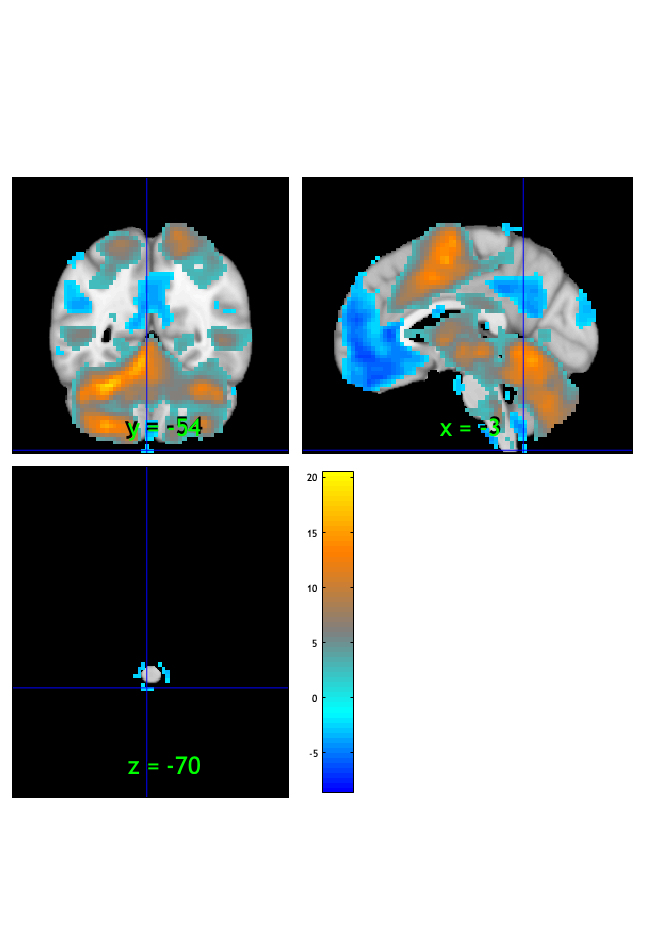

SPM12: spm_check_registration (v7759)              17:45:57 - 12/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×36 struct}


orthviews(fdr_t)

drawnow, snapnow;

create_figure('montage'); axis off
montage(fdr_t)

Setting up fmridisplay objects


sagittal montage: 1484 voxels displayed, 57462 not displayed on these slices


sagittal montage: 1563 voxels displayed, 57383 not displayed on these slices


sagittal montage: 1520 voxels displayed, 57426 not displayed on these slices


axial montage: 10696 voxels displayed, 48250 not displayed on these slices


axial montage: 11527 voxels displayed, 47419 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: '/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


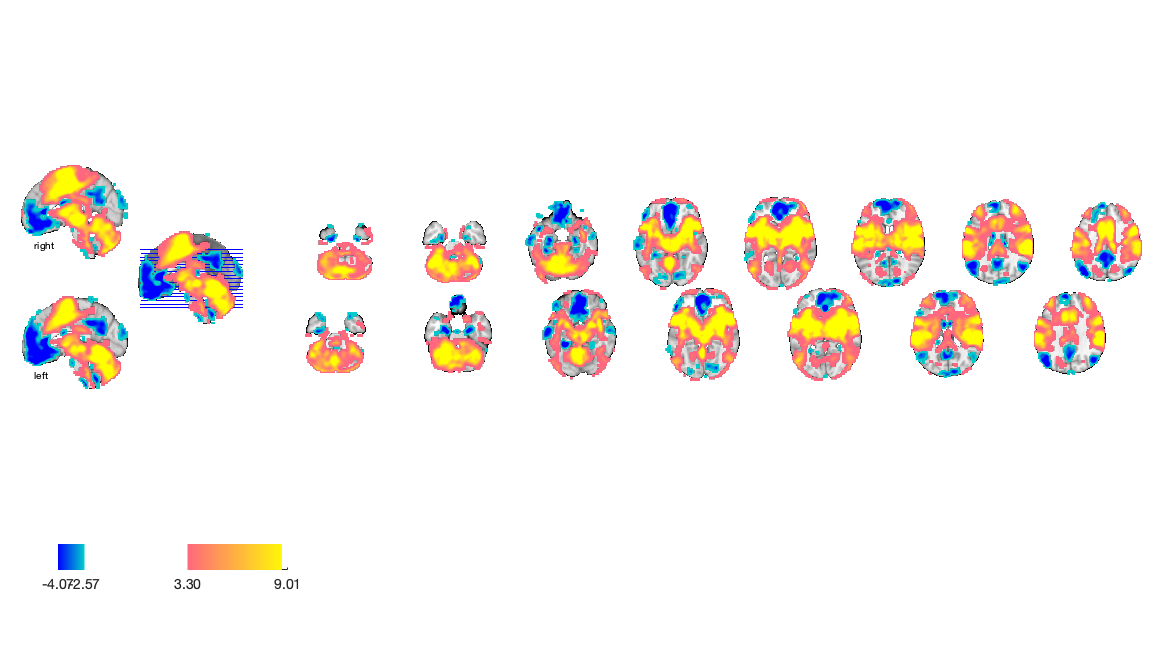

drawnow, snapnow;

## Vicarious dummy

clear all

#### Vicarious :: load dataset

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-03_CEScsA_24dofcsd/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0019.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.


sampleto = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-03_CEScsA_24dofcsd/1stLevel/sub-0008/con_0019.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 22363488 bytes
Loading image number:    56
Elapsed time is 5.276836 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 5415394  Bit rate: 22.37 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C',...
    'cueXcue_P', 'cueXcue_V', 'cueXcue_C',...
    'stim_P', 'stim_V', 'stim_C',...
    'stimXcue_P', 'stimXcue_V', 'stimXcue_C',...
    'stimXint_P', 'stimXint_V', 'stimXint_C',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C','simple_cue_G',...
    'simple_cueXcue_P', 'simple_cueXcue_V', 'simple_cueXcue_C','simple_cueXcue_G', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C','simple_stim_G',...
    'simple_stimXcue_P', 'simple_stimXcue_V', 'simple_stimXcue_C','simple_stimXcue_G',...
    'simple_stimXint_P', 'simple_stimXint_V','simple_stimXint_C', 'simple_stimXint_G'};

#### Vicarious :: `check data coverage`

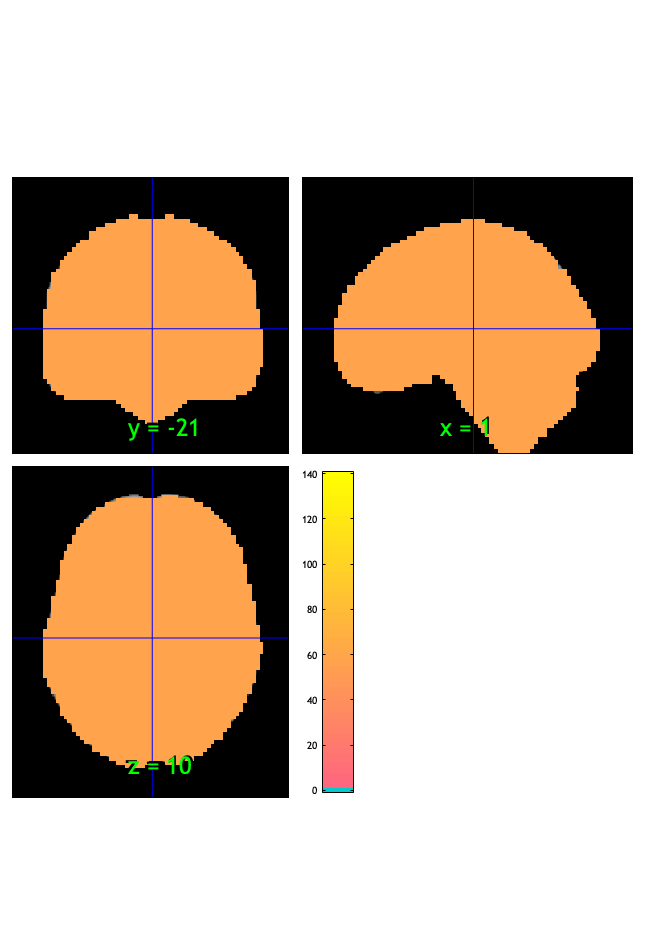

SPM12: spm_check_registration (v7759)              17:46:15 - 12/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

#### Vicarious :: Plot diagnostics, before l2norm

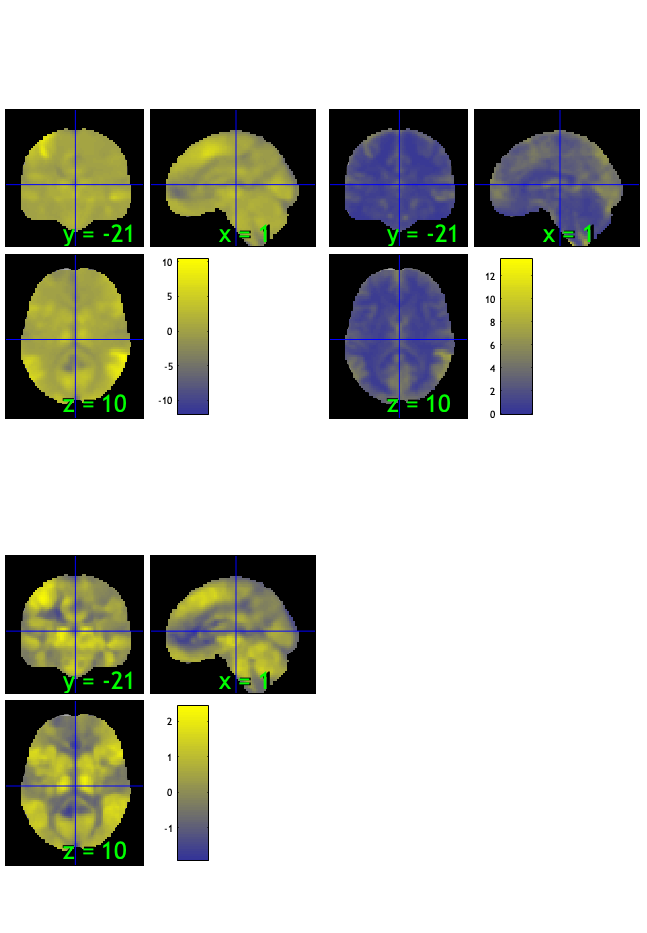

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 6 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 39.29%
Expected 2.80 outside 95% ellipsoid, found   7

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 25 41 
Uncorrected: 7 images		Cases 5 25 31 34 36 41 44 

Retained 6 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 48.21%
Expected 2.80 outside 95% ellipsoid, found   1

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 46 
Uncorrected: 1 images		Cases 46 

Mahalanobis (cov and corr, q<0.05 corrected):
  3 images 
                               Outlier_count    Percentage
                               

SPM12: spm_check_registration (v7759)              17:46:39 - 12/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

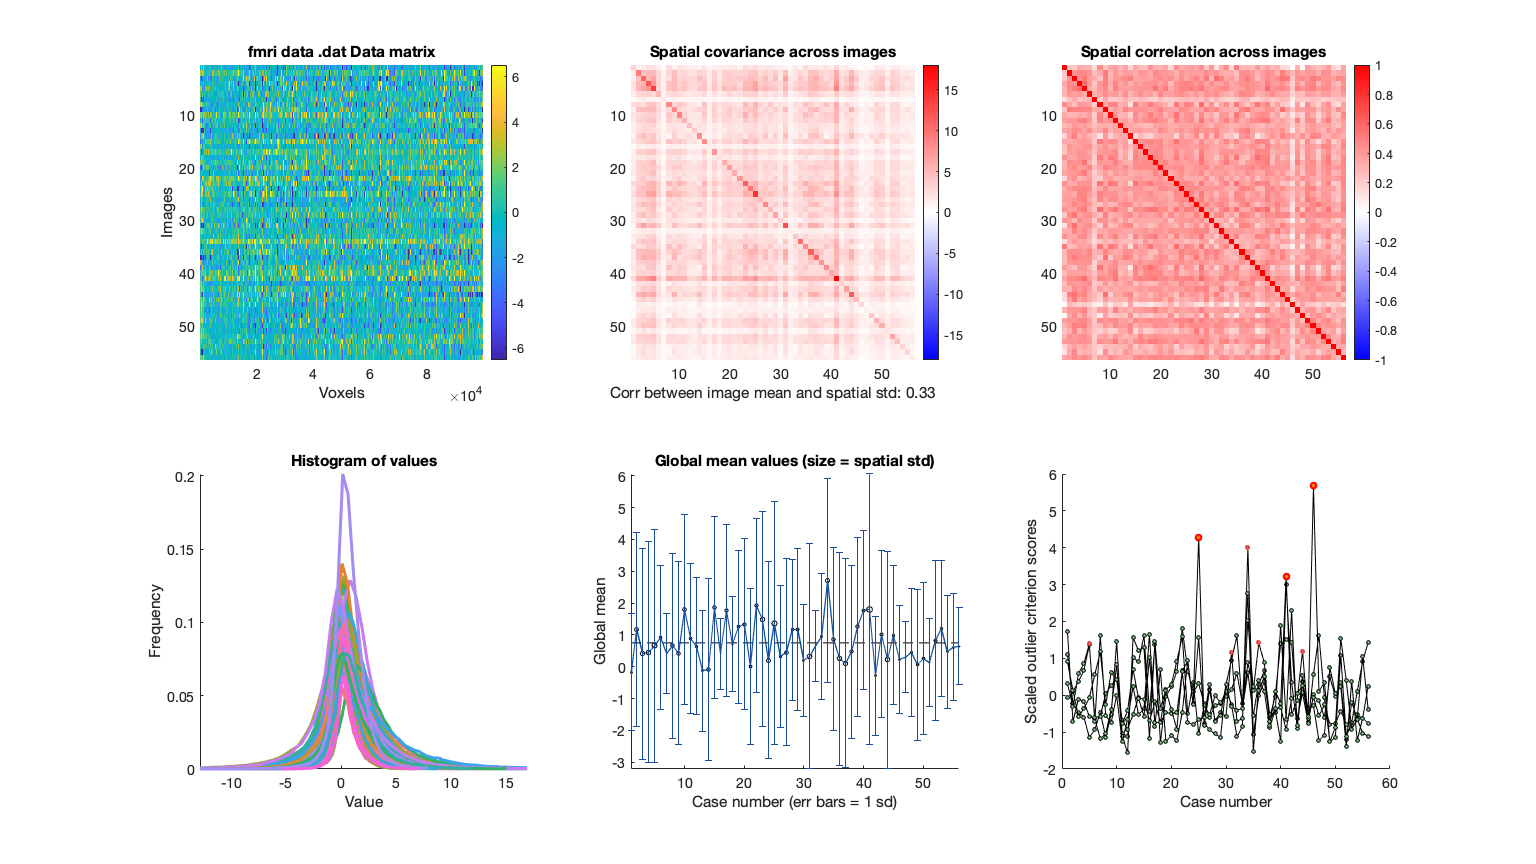

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


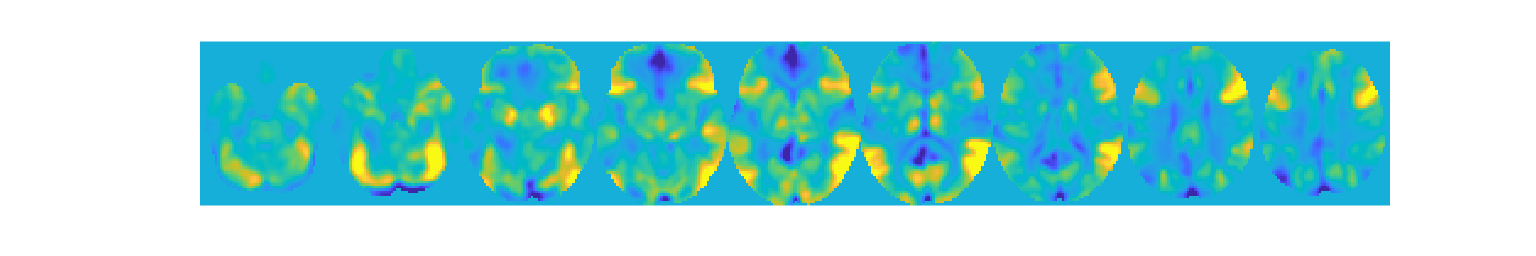

wh_outlier_uncorr = 56×1 logical array
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0


wh_outlier_corr = 56×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### Vicarious :: run robfit

set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;

#### Vicarious :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))

current length is 56


%for s = 1:length(wh_outlier_corr)
  %  disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×53 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [53×12 char]
              fullpath: [56×118 char]
           files_exist: [56×1 logical]
               history:

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×53 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [53×12 char]
              fullpath: [53×118 char]
           files_exist: [56×1 logical]
               history:

con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×53 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [53×12 char]
              fullpath: [53×118 char]
           files_exist: [53×1 logical]
               history:

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 3 participants, size is now 53


#### Vicarious :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Vicarious :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


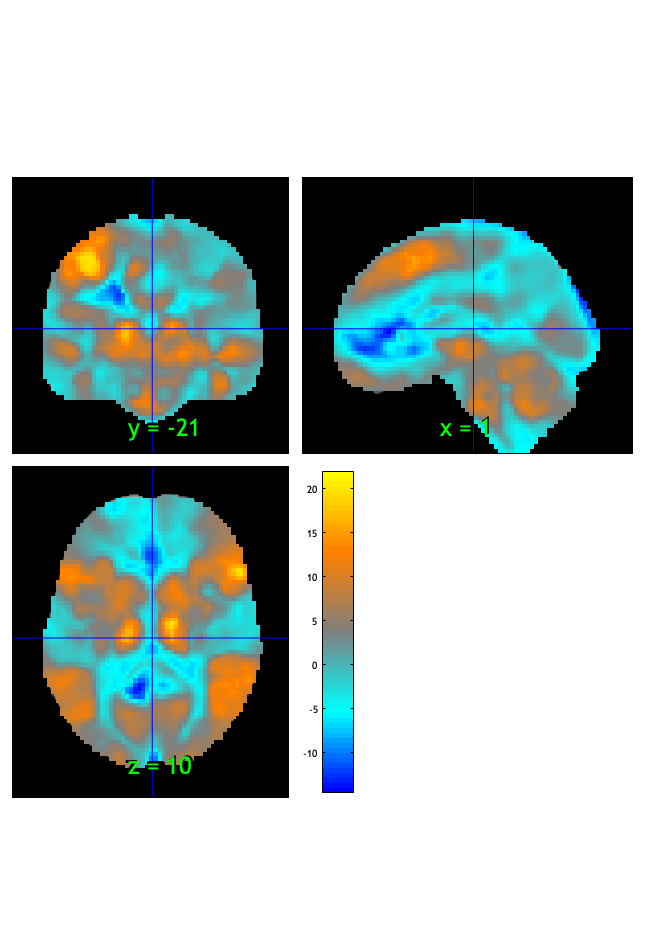

SPM12: spm_check_registration (v7759)              17:46:44 - 12/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×1 struct}


orthviews(t)

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.035660

Image   1
 19 contig. clusters, sizes   1 to 70725
Positive effect: 55268 voxels, min p-value: 0.00000000
Negative effect: 15938 voxels, min p-value: 0.00000000


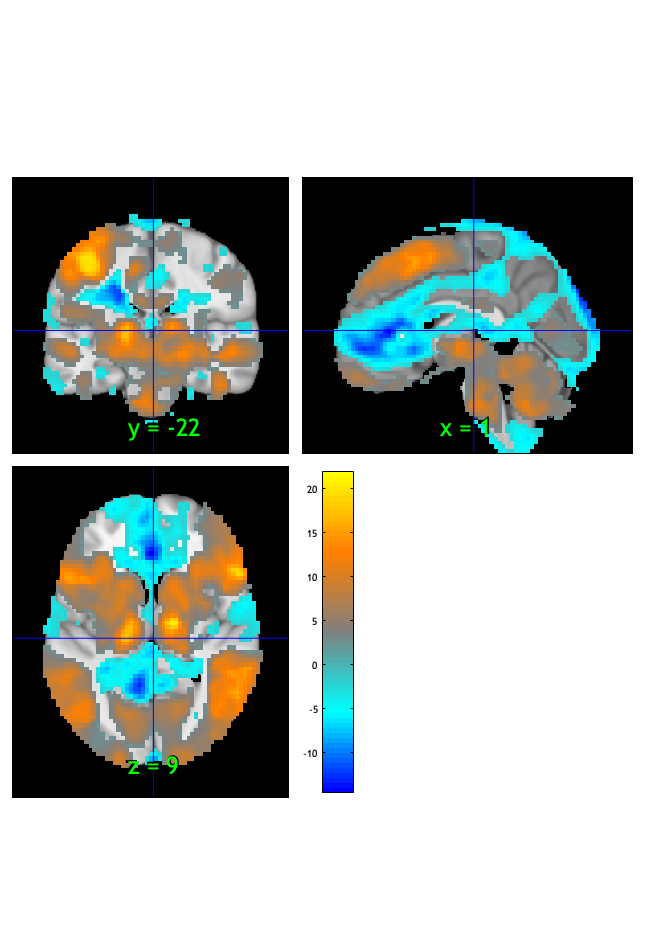

SPM12: spm_check_registration (v7759)              17:46:46 - 12/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×19 struct}


orthviews(fdr_t)

drawnow, snapnow;

create_figure('montage'); axis off
montage(fdr_t)

Setting up fmridisplay objects


sagittal montage: 1825 voxels displayed, 69381 not displayed on these slices


sagittal montage: 1727 voxels displayed, 69479 not displayed on these slices


sagittal montage: 1729 voxels displayed, 69477 not displayed on these slices


axial montage: 13547 voxels displayed, 57659 not displayed on these slices


axial montage: 14577 voxels displayed, 56629 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: '/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


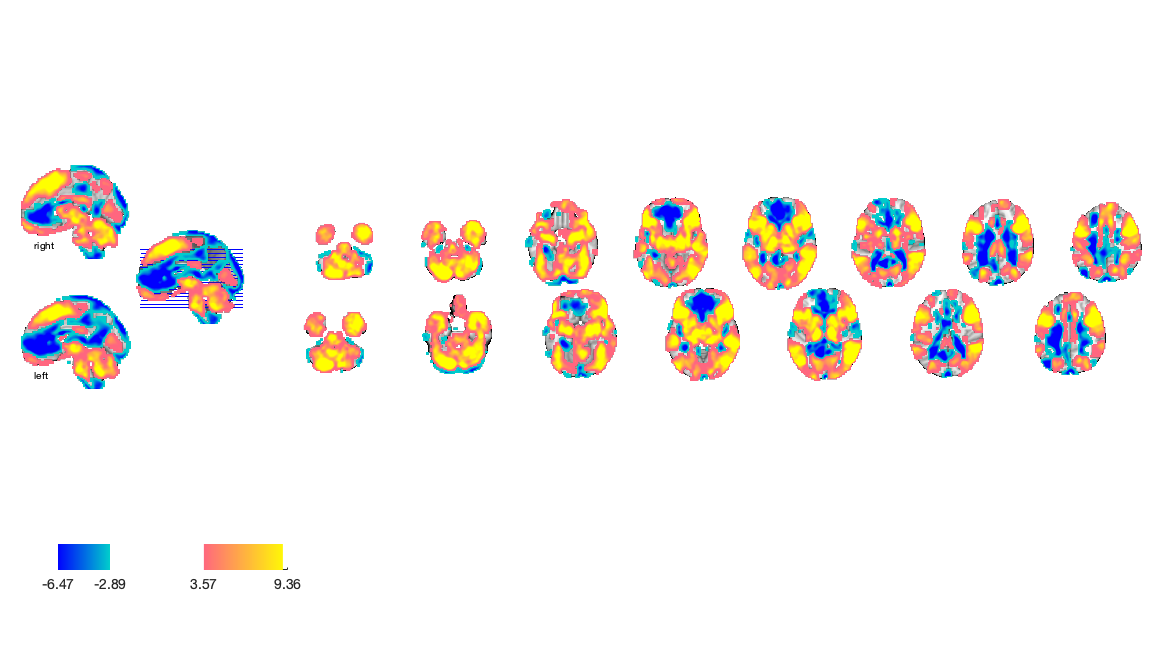

drawnow, snapnow;

## Cognitive dummy

#### Cognitive :: load dataset

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-03_CEScsA_24dofcsd/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0020.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii


sampleto = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-03_CEScsA_24dofcsd/1stLevel/sub-0008/con_0020.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 22363488 bytes
Loading image number:    56
Elapsed time is 5.366205 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 5431577  Bit rate: 22.37 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C',...
    'cueXcue_P', 'cueXcue_V', 'cueXcue_C',...
    'stim_P', 'stim_V', 'stim_C',...
    'stimXcue_P', 'stimXcue_V', 'stimXcue_C',...
    'stimXint_P', 'stimXint_V', 'stimXint_C',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C','simple_cue_G',...
    'simple_cueXcue_P', 'simple_cueXcue_V', 'simple_cueXcue_C','simple_cueXcue_G', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C','simple_stim_G',...
    'simple_stimXcue_P', 'simple_stimXcue_V', 'simple_stimXcue_C','simple_stimXcue_G',...
    'simple_stimXint_P', 'simple_stimXint_V','simple_stimXint_C', 'simple_stimXint_G'};

#### Cognitive :: `check data coverage`

SPM12: spm_check_registration (v7759)              17:47:08 - 12/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

#### Cognitive :: Plot diagnostics, before l2norm

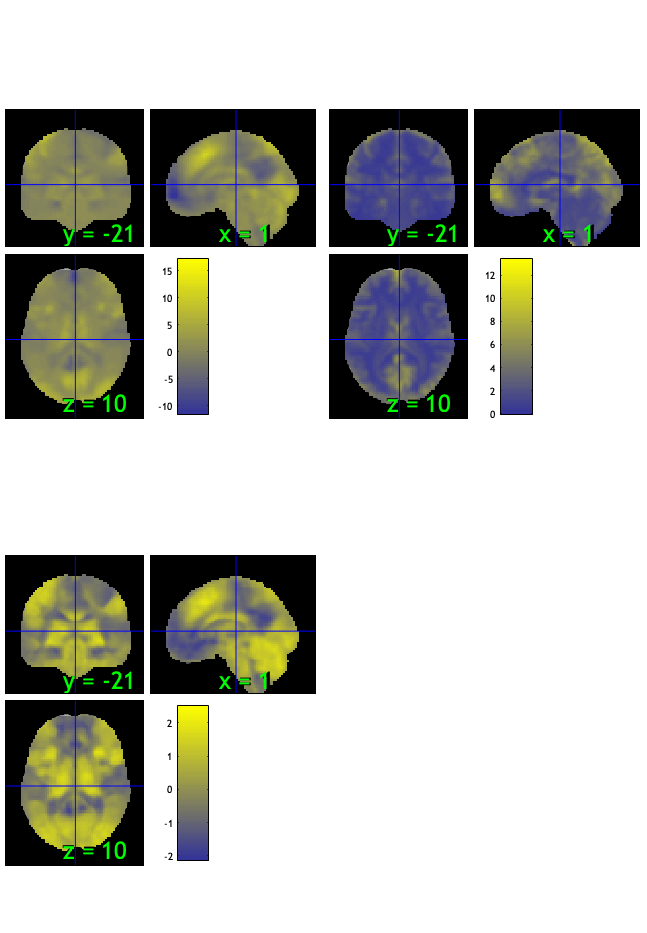

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 4 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 33.93%
Expected 2.80 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 25 34 
Uncorrected: 5 images		Cases 20 25 34 41 45 

Retained 11 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 35.71%
Expected 2.80 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 6 images		Cases 7 30 32 46 54 55 

Mahalanobis (cov and corr, q<0.05 corrected):
  2 images 
                               Outlier_count    Percentage
                          

SPM12: spm_check_registration (v7759)              17:47:25 - 12/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

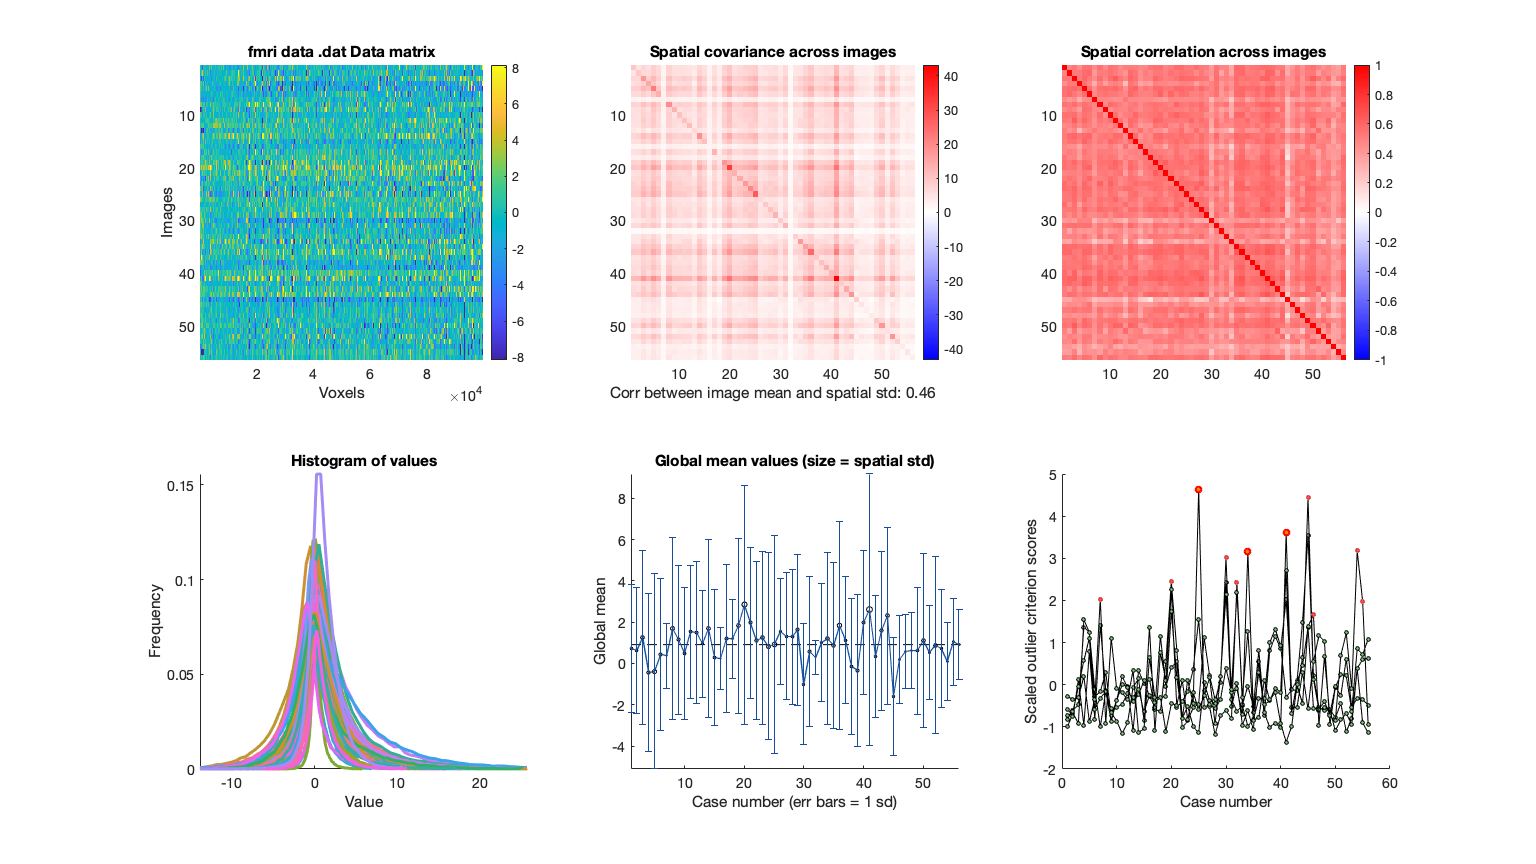

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


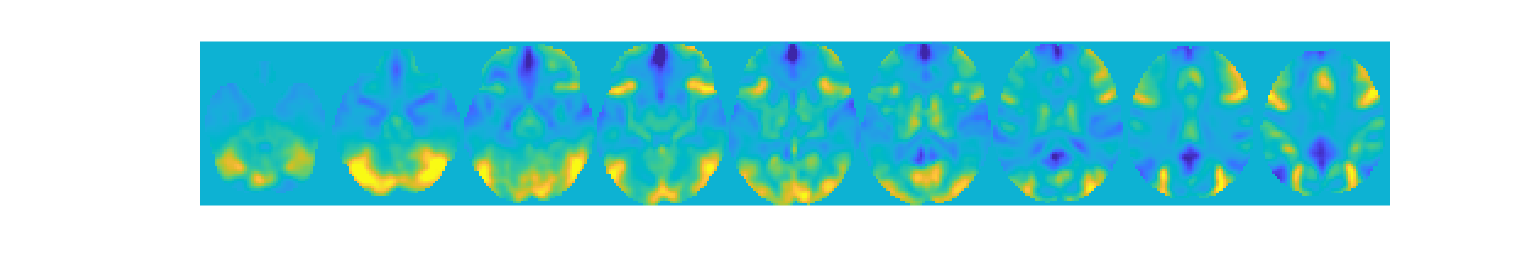

wh_outlier_uncorr = 56×1 logical array
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0


wh_outlier_corr = 56×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### Cognitive :: run robfit

set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;

#### Cognitive :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))

current length is 56


%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×53 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [53×12 char]
              fullpath: [56×118 char]
           files_exist: [56×1 logical]
               history:

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×53 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [53×12 char]
              fullpath: [53×118 char]
           files_exist: [56×1 logical]
               history:

con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×53 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [53×12 char]
              fullpath: [53×118 char]
           files_exist: [53×1 logical]
               history:

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 3 participants, size is now 53


#### Cognitive:: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Cognitive :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


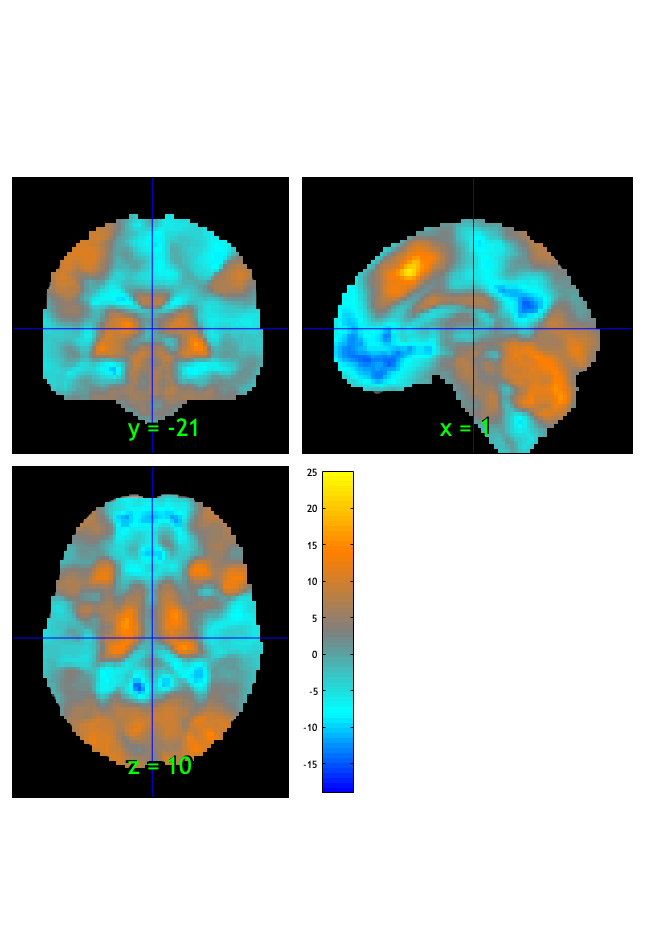

SPM12: spm_check_registration (v7759)              17:47:30 - 12/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×1 struct}


orthviews(t)

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.038529

Image   1
  8 contig. clusters, sizes   1 to 76941
Positive effect: 49148 voxels, min p-value: 0.00000000
Negative effect: 27824 voxels, min p-value: 0.00000000


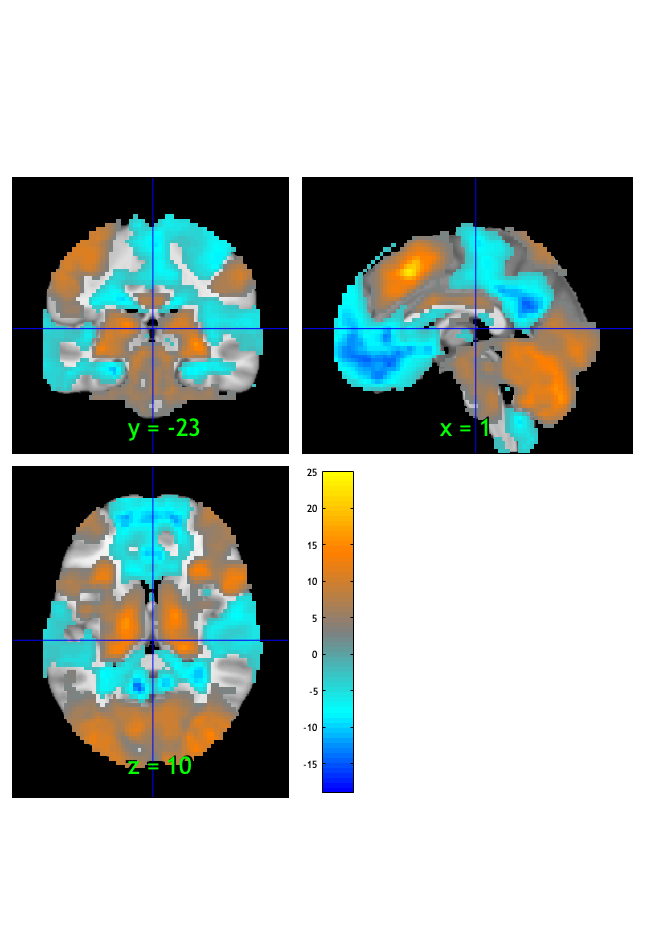

SPM12: spm_check_registration (v7759)              17:47:32 - 12/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×8 struct}


orthviews(fdr_t)

drawnow, snapnow;

create_figure('montage'); axis off
montage(fdr_t)

Setting up fmridisplay objects


sagittal montage: 1922 voxels displayed, 75050 not displayed on these slices


sagittal montage: 1927 voxels displayed, 75045 not displayed on these slices


sagittal montage: 1900 voxels displayed, 75072 not displayed on these slices


axial montage: 14639 voxels displayed, 62333 not displayed on these slices


axial montage: 15437 voxels displayed, 61535 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: '/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


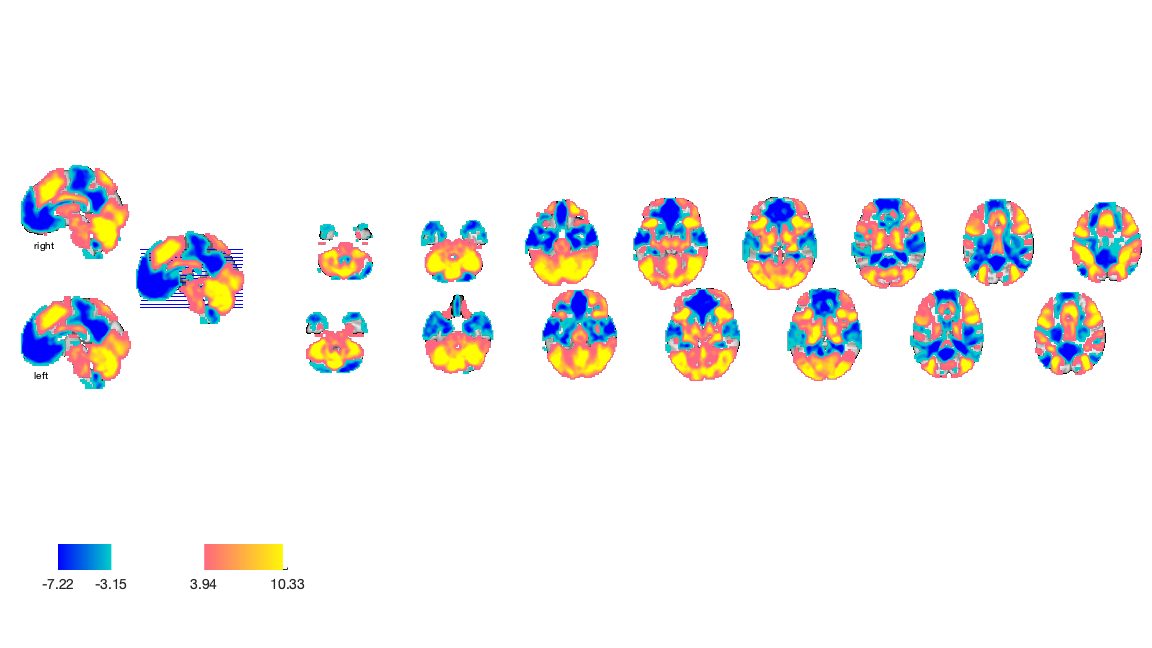

drawnow, snapnow;

## General dummy

#### General :: load dataset

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-03_CEScsA_24dofcsd/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0021.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii


sampleto = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-03_CEScsA_24dofcsd/1stLevel/sub-0008/con_0021.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 22363488 bytes
Loading image number:    56
Elapsed time is 5.001958 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 5405306  Bit rate: 22.37 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C',...
    'cueXcue_P', 'cueXcue_V', 'cueXcue_C',...
    'stim_P', 'stim_V', 'stim_C',...
    'stimXcue_P', 'stimXcue_V', 'stimXcue_C',...
    'stimXint_P', 'stimXint_V', 'stimXint_C',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C','simple_cue_G',...
    'simple_cueXcue_P', 'simple_cueXcue_V', 'simple_cueXcue_C','simple_cueXcue_G', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C','simple_stim_G',...
    'simple_stimXcue_P', 'simple_stimXcue_V', 'simple_stimXcue_C','simple_stimXcue_G',...
    'simple_stimXint_P', 'simple_stimXint_V','simple_stimXint_C', 'simple_stimXint_G'};

#### General :: `check data coverage`

SPM12: spm_check_registration (v7759)              17:47:50 - 12/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

#### General :: Plot diagnostics, before l2norm

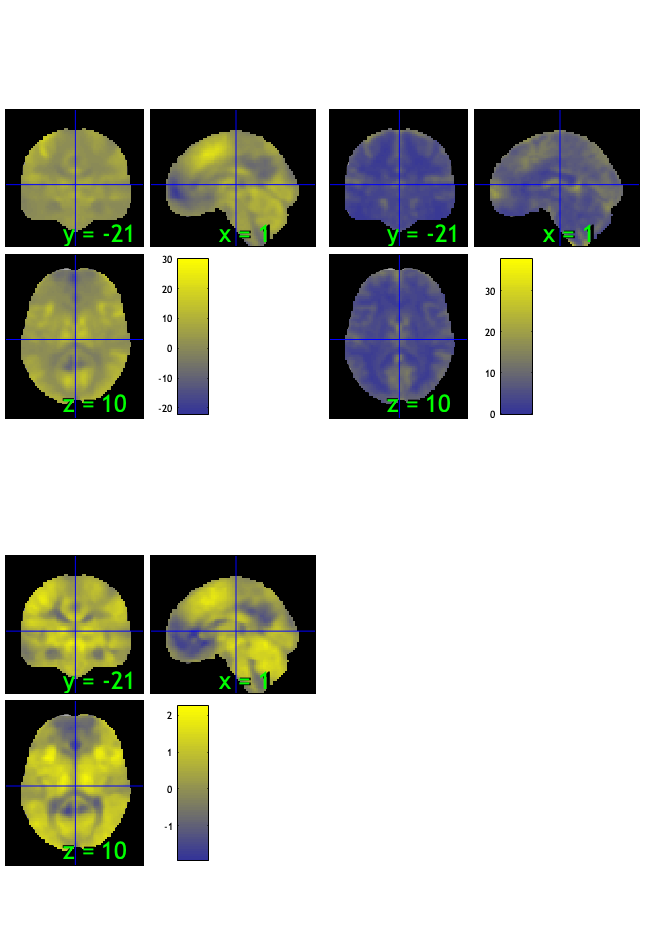

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 33.93%
Expected 2.80 outside 95% ellipsoid, found   4

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 20 
Uncorrected: 4 images		Cases 10 20 23 29 

Retained 11 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 37.50%
Expected 2.80 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 7 
Uncorrected: 5 images		Cases 7 29 30 54 55 

Mahalanobis (cov and corr, q<0.05 corrected):
  2 images 
                               Outlier_count    Percentage
                               

SPM12: spm_check_registration (v7759)              17:48:07 - 12/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

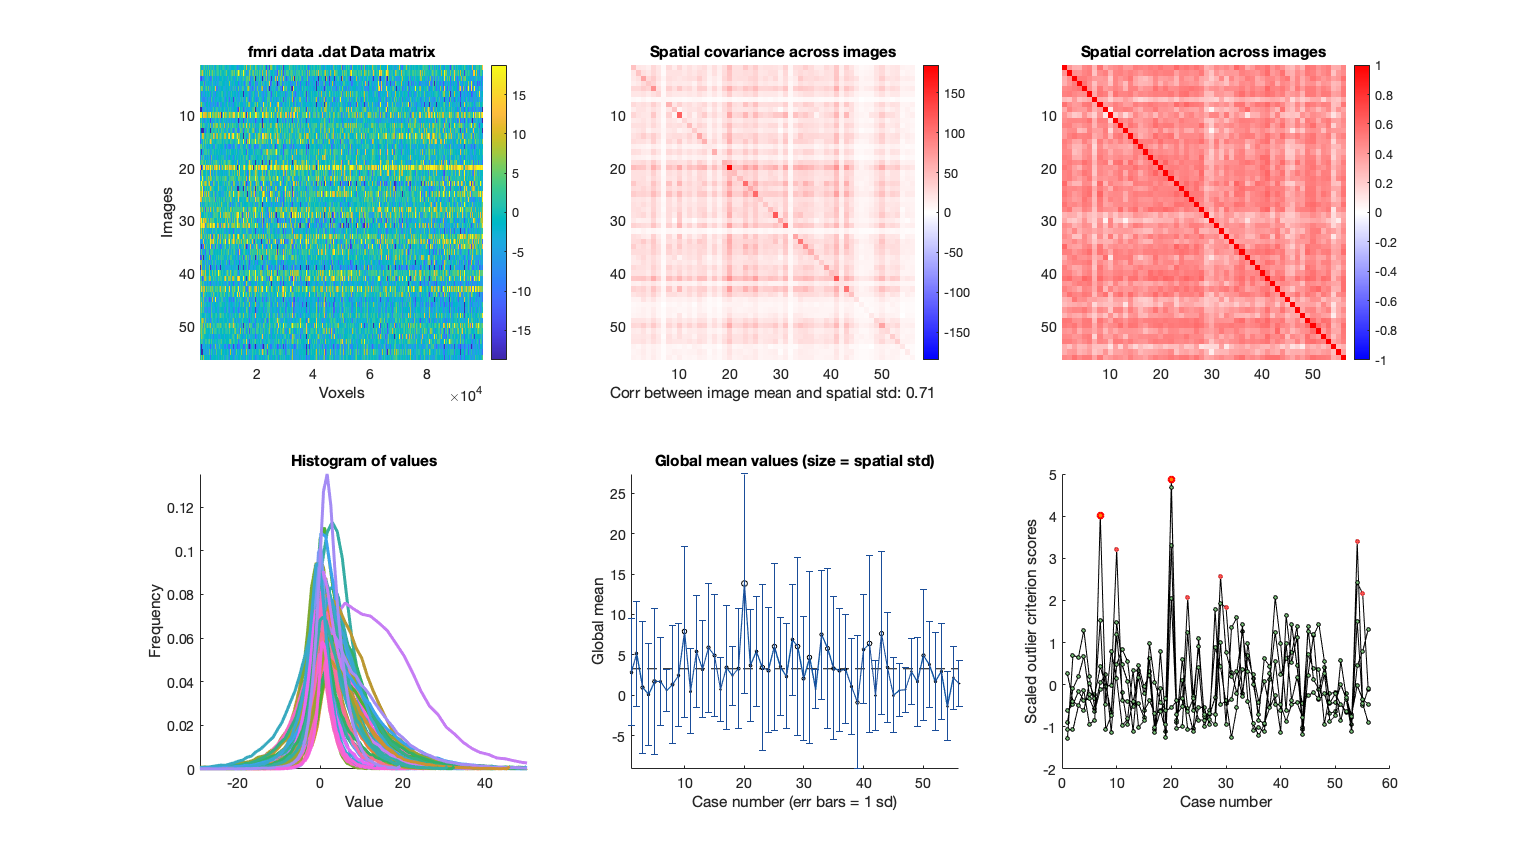

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


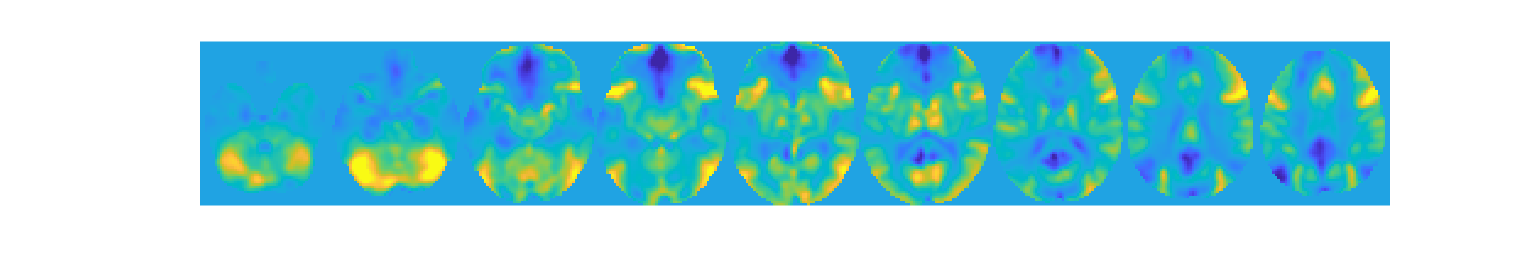

wh_outlier_uncorr = 56×1 logical array
   0
   0
   0
   0
   0
   0
   1
   0
   0
   1


wh_outlier_corr = 56×1 logical array
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj)

#### General :: run robfit

set(gcf,'Visible','on')
figure ('Visible', 'on');
drawnow, snapnow;

#### General :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))))

current length is 56


%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×54 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [54×12 char]
              fullpath: [56×118 char]
           files_exist: [56×1 logical]
               history:

con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×54 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [54×12 char]
              fullpath: [54×118 char]
           files_exist: [56×1 logical]
               history:

con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:)

con =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'REMOVED: CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [99837×54 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: [54×12 char]
              fullpath: [54×118 char]
           files_exist: [54×1 logical]
               history:

%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))))

after removing 2 participants, size is now 54


#### General:: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### General :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


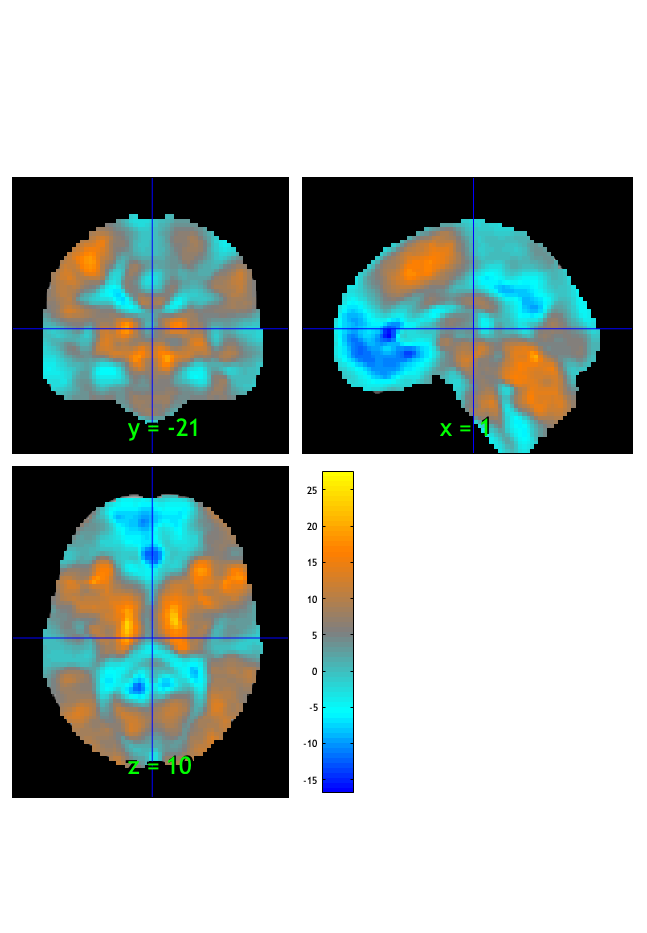

SPM12: spm_check_registration (v7759)              17:48:12 - 12/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


ans = 1×1 cell array
    {1×1 struct}


orthviews(t)

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.038342

Image   1
 19 contig. clusters, sizes   1 to 76387
Positive effect: 63371 voxels, min p-value: 0.00000000
Negative effect: 13223 voxels, min p-value: 0.00000000


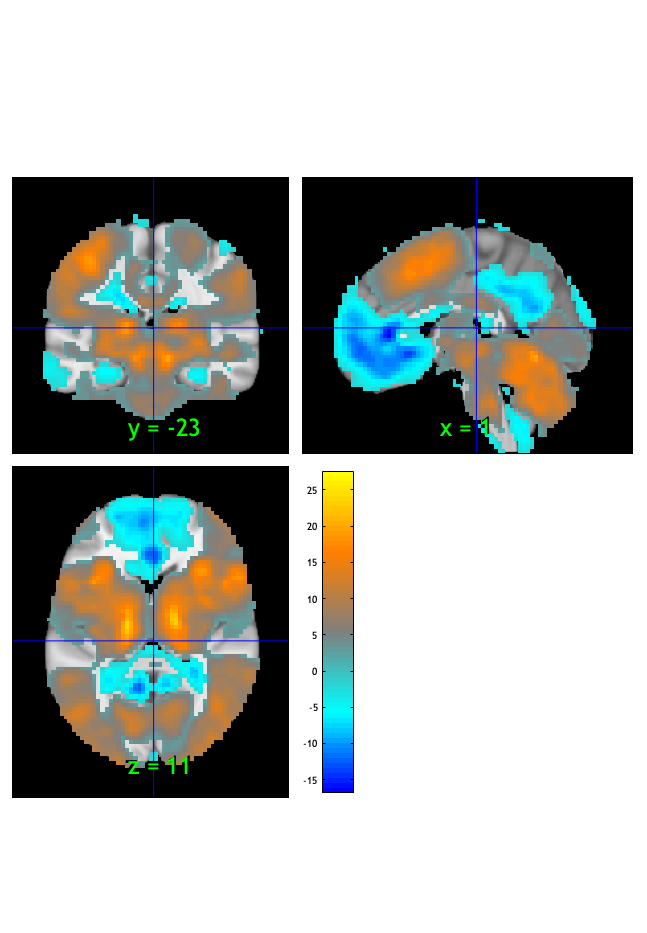

SPM12: spm_check_registration (v7759)              17:48:13 - 12/06/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


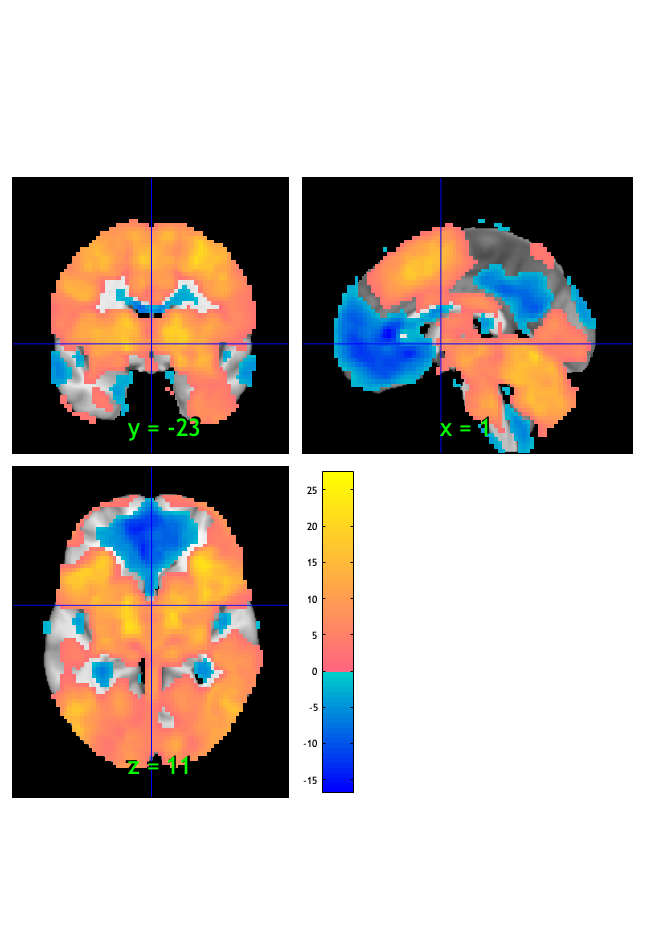

ans = 1×1 cell array
    {1×19 struct}


orthviews(fdr_t)

drawnow, snapnow;

create_figure('montage'); axis off
montage(fdr_t)

Setting up fmridisplay objects


sagittal montage: 1896 voxels displayed, 74698 not displayed on these slices


sagittal montage: 1873 voxels displayed, 74721 not displayed on these slices


sagittal montage: 1842 voxels displayed, 74752 not displayed on these slices


axial montage: 14334 voxels displayed, 62260 not displayed on these slices


axial montage: 15378 voxels displayed, 61216 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: '/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


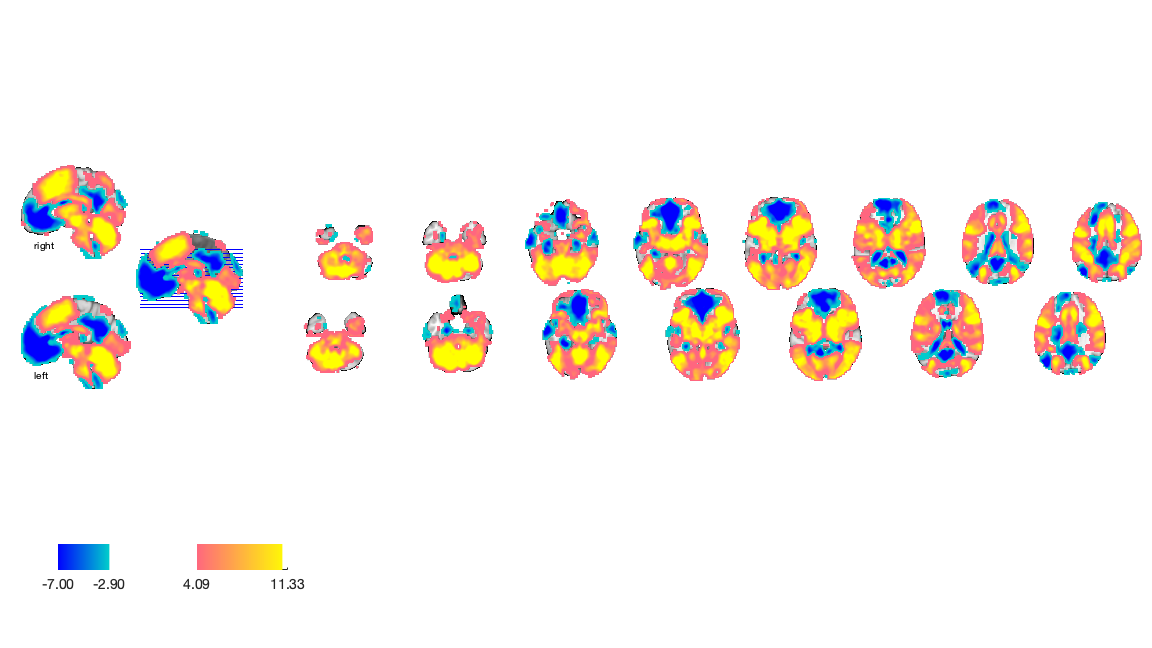

drawnow, snapnow;